clear,clc
% Load the digitalized data
data = readtable('digitized_data_AL.csv')

data = 3487×2 table
     Time     Ankle_Angle
    ______    ___________

         0          10   
    0.9981          10   
         0      9.9364   
    0.9981      9.9364   
         0      9.8728   
    0.9981      9.8728   
         0      9.8092   
    0.9981      9.8092   
         0      9.7455   
    0.9981      9.7455   
         0      9.6819   
    0.9981      9.6819   
         0      9.6183   
    0.9981      9.6183   
         0      9.5547   
    0.9981      9.5547   


data= data(data.Time ~= 0,:)

data = 3098×2 table
     Time      Ankle_Angle
    _______    ___________

     0.9981          10   
     0.9981      9.9364   
     0.9981      9.8728   
     0.9981      9.8092   
     0.9981      9.7455   
     0.9981      9.6819   
     0.9981      9.6183   
     0.9981      9.5547   
     0.9981      9.4911   
     0.9981      9.4275   
     0.9981      9.3639   
     0.9981      9.3003   
     0.9981      9.2366   
    0.93162       9.173   
     0.9981       9.173   
    0.92498      9.1094   


data = data(data.Time <=0.96,:)

data = 2705×2 table
     Time      Ankle_Angle
    _______    ___________

    0.93162       9.173   
    0.92498      9.1094   
    0.92593      9.1094   
    0.92688      9.1094   
    0.92783      9.1094   
    0.92877      9.1094   
    0.92972      9.1094   
    0.93067      9.1094   
    0.93257      9.1094   
    0.93352      9.1094   
    0.93447      9.1094   
    0.93542      9.1094   
    0.93637      9.1094   
    0.93732      9.1094   
    0.93827      9.1094   
    0.91928      9.0458   


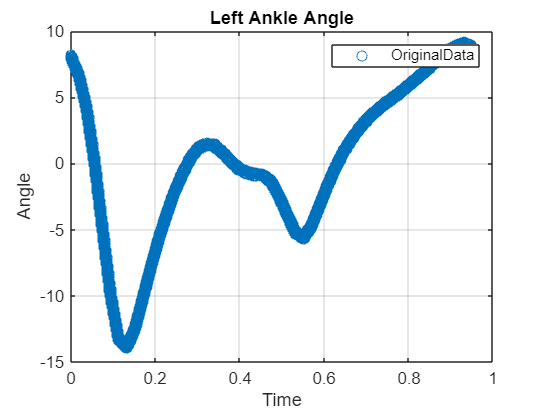

time = data.Time;
angle = data.Ankle_Angle;
plot(time,angle,'o','DisplayName','OriginalData');
xlabel('Time');
ylabel('Angle');
title('Left Ankle Angle');
legend;
grid on;

% Remove outliers
validRange =[-15,10]

validRange =    -15    10



% Save the filtered data to a new CSV file
%writetable(data, 'filtered_data.csv');
disp('Filtered data saved to "filtered_data.csv"');

Filtered data saved to "filtered_data.csv"
